# Acoustic properties of vocalizations used for neural data analysis

List of cells

Path2AllData = '/Volumes/JulieE8T/LMCResults';
% Load the List of cells as established by population_PCA_GLM.mlx
load(fullfile(Path2AllData,'population_PCA_GLM_data.mat'),'ListCells','GoodCellIndices','OperantVocalizer','BaorTr_0ind');
% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from vocalizer of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGV = ListCellsG(logical(OperantVocalizer.*BaorTr_0ind));
fprintf(1, 'There are %d/%d cells from Hodor (ID 59834)\nThere are %d/%d cells from Cooper (ID 11689)', sum(contains(ListCellsGV, '59834')),length(ListCellsGV),sum(contains(ListCellsGV, '11689')),length(ListCellsGV))

There are 476/596 cells from Hodor (ID 59834)
There are 120/596 cells from Cooper (ID 11689)


% Import Biosound library
py.importlib.import_module('soundsig')

ans =   Python module with properties:

          signal: [1×1 py.module]
    detect_peaks: [1×1 py.module]
           sound: [1×1 py.module]
        timefreq: [1×1 py.module]

    <module 'soundsig' from '/Users/elie/anaconda3/lib/python3.7/site-packages/soundsig/__init__.py'>


Calculate the MPS of all vocalizations, as recorded from microphone or as recorded from the piezo, The voclaization is placed within a minimum window size 

% % Window size for trills
% load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'StimDuraMax');
% StimDuraOptTrills = round(mean(StimDuraMax)/10)*10;
% % Window size for non-Trills
% load(fullfile(Path2AllData,'DistanceNeuroAcoustic_nonTrills_data.mat'), 'StimDuraMax');
% StimDuraOptnonTrills = round(mean(StimDuraMax)/10)*10;
% clear StimDuraMax
RecDevice = 'Mic'; %set to 'Mic' or 'Piezo'
StimDuraMin = 150; % place vocalization into a minimum vector of 150ms but take the whole vocalization section otherwise
for cc=1:length(ListCellsGV)
    [~,Filecc1] = fileparts(ListCellsGV{cc});
    if cc>1 
        [~,Filecc2] = fileparts(ListCellsGV{cc-1});
        if strcmp(Filecc1(1:14),Filecc2(1:14))
            % we have already gathered these data, skip
            continue
        end
    end
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, length(ListCellsGV))
    Cell = load(ListCellsGV{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'Voc') .* contains(Cell.ExpType, 'O'));
        
    end
    Voc_mps = cell(length(IndVoc),1);
    Voc_what = cell(length(IndVoc),1);
    Voc_who = cell(length(IndVoc),1);
    % Calculate the MPS and save it
    for NStim=1:length(IndVoc)
        if strcmp(RecDevice, 'Mic')
            SoundCol = 1;
            MaxFreq = 50000;
        elseif strcmp(RecDevice, 'Piezo') 
            SoundCol = 2;
            MaxFreq = 10000; % signal already filtered at 10k in what calls...
        else
            error('Recording device wrongly set')
        end
        FS = Cell.BioSound{IndVoc(NStim),SoundCol}.samprate;
        
        Sound = Cell.BioSound{IndVoc(NStim),SoundCol}.sound;
        if (Sound/FS*10^3)<StimDuraMin
            Y = zeros(round(StimDuraMin*FS/10^3),1);
            Y(1:length(Sound)) = Sound;
        else
            Y=Sound;
        end
        [MPS, Wf, Wt] = mps_calc(Y, FS, MaxFreq);
        if NStim>1
            if any(round(Voc_wf.*10^4) ~= round(Wf.*10^4))
                keyboard
            end
            if any(round(Voc_wt) ~= round(Wt))
                keyboard
            end
        end
        Voc_wt = Wt;
        Voc_wf = Wf;
        Voc_what{NStim} = Cell.What{IndVoc(NStim)}; 
        Voc_who{NStim} = Cell.Who{IndVoc(NStim)};
        Voc_mps{NStim}= reshape(MPS, numel(MPS),1);
    end
    if strcmp(RecDevice, 'Mic')
        Outname = fullfile(Path2AllData, [Filecc1(1:14) '_MPSMic.mat']);
        fprintf(1,'\nSaving %s\n',Outname)
        save(Outname, 'Voc_mps', 'Voc_wt', 'Voc_wf','IndVoc', 'Voc_what', 'Voc_who')
    elseif strcmp(RecDevice, 'Piezo')
        Outname = fullfile(Path2AllData, [Filecc1(1:14) '_MPSPiezo.mat']);
        fprintf(1,'\nSaving %s\n',Outname)
        save(Outname, 'Voc_mps', 'Voc_wt', 'Voc_wf','IndVoc', 'Voc_what', 'Voc_who')
    end
end

Cell 1/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190604_MPSMic.mat


Cell 16/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190605_MPSMic.mat


Cell 28/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190606_MPSMic.mat


Cell 33/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190607_MPSMic.mat


Cell 40/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190610_MPSMic.mat


Cell 42/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190611_MPSMic.mat


Cell 53/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190612_MPSMic.mat


Cell 67/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190613_MPSMic.mat


Cell 78/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190614_MPSMic.mat


Cell 91/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190616_MPSMic.mat


Cell 107/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190617_MPSMic.mat


Cell 116/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190618_MPSMic.mat


Cell 131/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190619_MPSMic.mat


Cell 155/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190620_MPSMic.mat


Cell 173/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190621_MPSMic.mat


Cell 186/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190622_MPSMic.mat


Cell 199/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190623_MPSMic.mat


Cell 219/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190624_MPSMic.mat


Cell 236/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190625_MPSMic.mat


Cell 252/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190626_MPSMic.mat


Cell 264/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190627_MPSMic.mat


Cell 288/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190628_MPSMic.mat


Cell 303/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190629_MPSMic.mat


Cell 324/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190630_MPSMic.mat


Cell 338/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190701_MPSMic.mat


Cell 359/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190702_MPSMic.mat


Cell 376/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190704_MPSMic.mat


Cell 389/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190705_MPSMic.mat


Cell 407/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190706_MPSMic.mat


Cell 425/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190707_MPSMic.mat


Cell 441/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190708_MPSMic.mat


Cell 455/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190710_MPSMic.mat


Cell 465/596



Saving /Volumes/JulieE8T/LMCResults/59834_20190711_MPSMic.mat


Cell 477/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190116_MPSMic.mat


Cell 485/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190117_MPSMic.mat


Cell 492/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190118_MPSMic.mat


Cell 493/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190119_MPSMic.mat


Cell 494/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190120_MPSMic.mat


Cell 498/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190123_MPSMic.mat


Cell 501/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190124_MPSMic.mat


Cell 505/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190125_MPSMic.mat


Cell 509/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190129_MPSMic.mat


Cell 516/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190130_MPSMic.mat


Cell 522/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190131_MPSMic.mat


Cell 537/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190201_MPSMic.mat


Cell 546/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190202_MPSMic.mat


Cell 557/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190204_MPSMic.mat


Cell 566/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190205_MPSMic.mat


Cell 575/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190206_MPSMic.mat


Cell 584/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190208_MPSMic.mat


Cell 585/596



Saving /Volumes/JulieE8T/LMCResults/11689_20190212_MPSMic.mat


## Calculations for first Bat

Gather Time varying PAF For first Bat

% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
StimDuraMax = 300; % duration in ms of trills according to script Explore Calls 97% of trills are within that time window for both vocalizer bats
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{1};
ListCellsGVBatID = ListCellsGV(contains(ListCellsGV,BatID));
NC = length(ListCellsGVBatID);
Trills_fund = cell(1,NC);
Trills_sal = cell(1,NC);
Trills_amp = cell(1,NC);
Trills_specMean = cell(1,NC);
Trills_formDisp = cell(1,NC);
Trills_spectroPiezoto = cell(1,NC);
Trills_spectroPiezofo = cell(1,NC);
Trills_spectroPiezo = cell(1,NC);
Trills_spectroMicto = cell(1,NC);
Trills_spectroMicfo = cell(1,NC);
Trills_spectroMic = cell(1,NC);
SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:length(ListCellsGVBatID)
    [~,Filecc1] = fileparts(ListCellsGVBatID{cc});
    if cc>1 
        [~,Filecc2] = fileparts(ListCellsGVBatID{cc-1});
        if strcmp(Filecc1(1:14),Filecc2(1:14))
            % we have already gather these data, skip
            continue
        end
    end
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, length(ListCellsGVBatID))
    Cell = load(ListCellsGVBatID{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') );
        
    end
    % initialize the matrix of acoustic values with nan or zeros 
    Trills_fund{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_sal{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_amp{cc} = zeros(StimDuraMax,length(IndVoc));
    Trills_specMean{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_formDisp{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_spectroPiezo{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    Trills_spectroMic{cc} = cell(1, length(IndVoc));
    Trills_spectroMicto{cc} = cell(1, length(IndVoc));
    Trills_spectroMicfo{cc} = cell(1, length(IndVoc));

    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:length(IndVoc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        if StimDur<=StimDuraMax
            TempFund = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span); % because of difference in sampling rate between micropphone and piezo and average calculations, sometimes the size of time varying biosound features in 1ms different....
            Trills_fund{cc}(1:length(TempFund),Nstim) = TempFund;
            Trills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            Trills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            Trills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            Trills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        else
            TempFund = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            Trills_fund{cc}(:,Nstim) = TempFund(1:StimDuraMax);
            TempSal = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            Trills_sal{cc}(:,Nstim) = TempSal(1:StimDuraMax);
            TempAmp = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            Trills_amp{cc}(:,Nstim) = TempAmp(1:StimDuraMax);
            TempSpecMean = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            Trills_specMean{cc}(:,Nstim) = TempSpecMean(1:StimDuraMax);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            TempFormDisp = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
            Trills_formDisp{cc}(:,Nstim) = TempFormDisp(1:StimDuraMax);
        end
        
        Trills_spectroPiezo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.spectro;
        Trills_spectroPiezoto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.to;
        Trills_spectroPiezofo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.fo;
        Trills_spectroMic{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.spectro;
        Trills_spectroMicto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.to;
        Trills_spectroMicfo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.fo;

    end
end

Cell 1/120
Cell 9/120
Cell 16/120
Cell 17/120
Cell 18/120
Cell 22/120
Cell 25/120
Cell 29/120
Cell 33/120
Cell 40/120
Cell 46/120
Cell 61/120
Cell 70/120
Cell 81/120
Cell 90/120
Cell 99/120
Cell 108/120
Cell 109/120


Trills_fund_mat = [Trills_fund{:}]';
Trills_sal_mat = [Trills_sal{:}]';
Trills_amp_mat = [Trills_amp{:}]';
Trills_specMean_mat = [Trills_specMean{:}]';
Trills_formDisp_mat = [Trills_formDisp{:}]';

% replace nan values by 0
% Trills_fund_mat(isnan(Trills_fund_mat)) = 0;
% Trills_sal_mat(isnan(Trills_sal_mat)) = 0;
% Trills_amp_mat(isnan(Trills_amp_mat)) = 0;
% Trills_specMean_mat(isnan(Trills_specMean_mat)) = 0;
% Trills_formDisp_mat(isnan(Trills_formDisp_mat)) = 0;


Plot the average vocalization

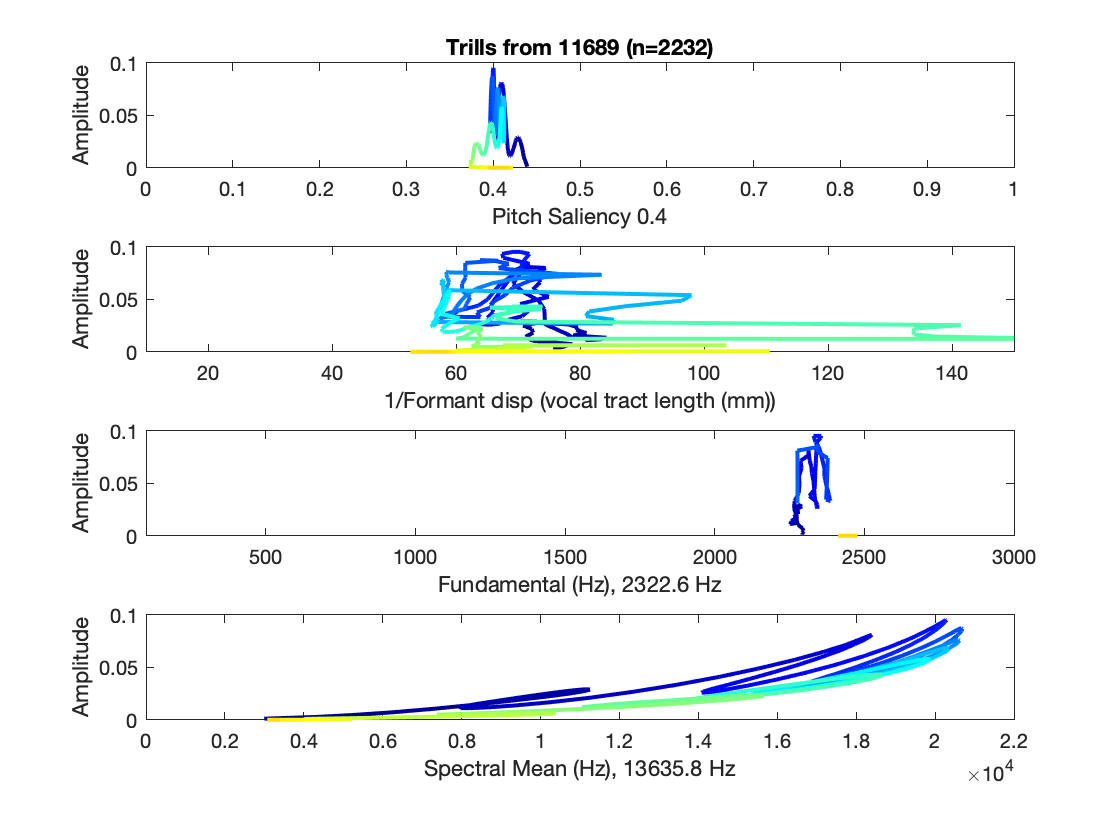



HalfSpan = (Span-1)/2;
% Plot the pitch saliency vs amplitude on microphone
figure()
subplot(4,1,1)
hold off
Saliency = mean(Trills_sal_mat, 'omitnan');
Amplitude = mean(Trills_amp_mat,'omitnan');
TimeSound = 1:size(Trills_sal_mat,2);
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
xlabel(sprintf('Pitch Saliency %.1f', mean(Saliency)))
ylabel('Amplitude')
title(sprintf('Trills from %s (n=%d)', BatID, size(Trills_amp_mat,1)))
hold off

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
hold off
FormantDisp = mean(Trills_formDisp_mat,'omitnan');
nx = length(FormantDisp);


for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
xlabel('1/Formant disp (vocal tract length (mm))')
ylabel('Amplitude')
hold off

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
hold off
SoundFund = mean(Trills_fund_mat,'omitnan');
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund, 'omitnan')))
    set(gca,'XLim',[100 3000])
end
hold off

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
hold off
SoundSpecMean = mean(Trills_specMean_mat,'omitnan');
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
    set(gca,'XLim',[0 22000])
end
hold off

Calculate the average MPS and the coefficient of variation MPS for each vocalizer to delineate the ROIs for each vocalizer

First look into Trills

RecDevice = 'Piezo'; %set to 'Mic' or 'Piezo'
AllMPSFiles = dir(fullfile(Path2AllData, ['*_MPS' RecDevice '.mat']));
AllMPSFiles = struct2cell(AllMPSFiles);
AllMPSFiles = AllMPSFiles(1,:)';
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{1};
BatMPSFiles = AllMPSFiles(contains(AllMPSFiles, BatID));
BatAllTrillsMPS = cell(1,length(BatMPSFiles));
for ff=1:length(BatMPSFiles)
    load(fullfile(Path2AllData, BatMPSFiles{ff}), 'Voc_mps', 'Voc_wt', 'Voc_wf','IndVoc', 'Voc_what', 'Voc_who');
    IndTrills = find(contains(Voc_what, 'Tr').*contains(Voc_who, 'self'));
    NTrills = length(IndTrills);
    BatAllTrillsMPS{ff} = nan(numel(Voc_mps{1}), NTrills);
    for tt=1:NTrills
        BatAllTrillsMPS{ff}(:,tt) = reshape(Voc_mps{IndTrills(tt)}, numel(Voc_mps{1}),1);
    end
end
BatAllTrillsMPS = [BatAllTrillsMPS{:}]';

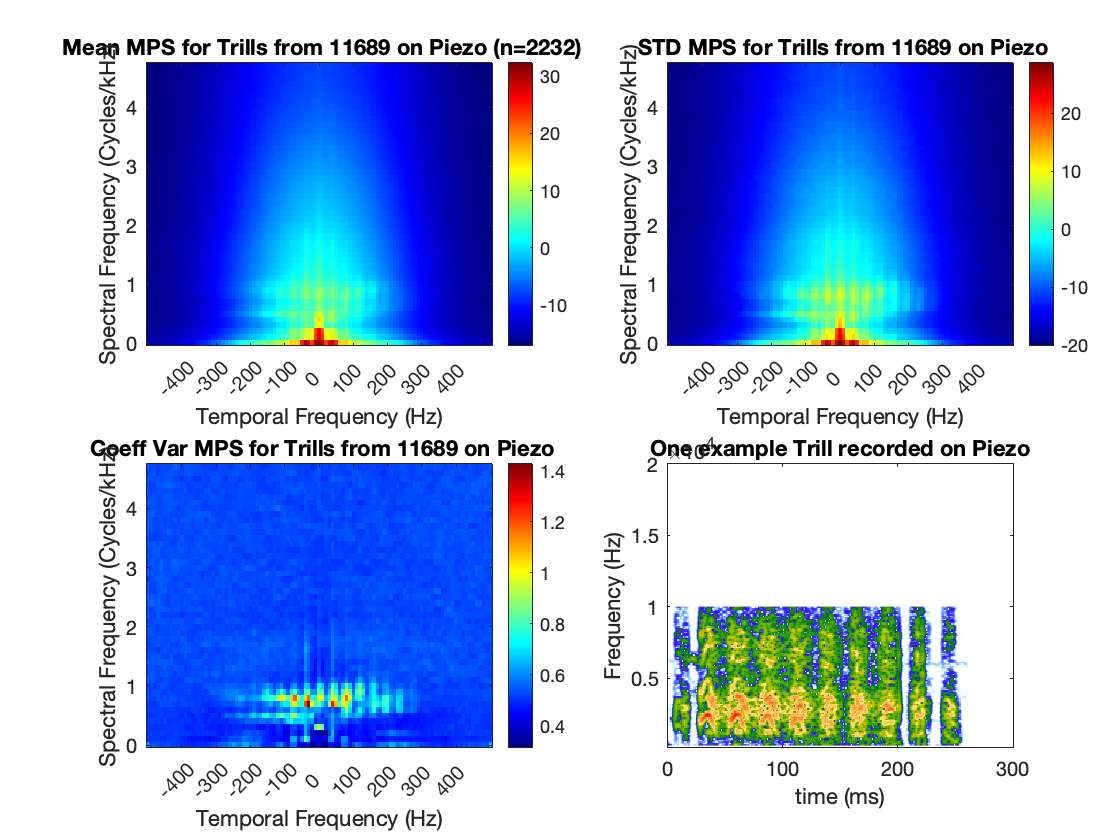

% plot the average and the STD mps now!
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(BatAllTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(MeanMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' Mean MPS for Trills from %s on %s (n=%d)', BatID, RecDevice, size(BatAllTrillsMPS,1)))

nexttile
STDMPS = reshape(std(BatAllTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(STDMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' STD MPS for Trills from %s on %s', BatID, RecDevice))

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0);
title(sprintf(' Coeff Var MPS for Trills from %s on %s',BatID, RecDevice))

% One spectrogram example

nexttile
StimID =2;
if strcmp(RecDevice, 'Mic')
    DayExample = find(~cellfun('isempty', Trills_spectroMic),1,'last');
    plot_spectro(Trills_spectroMic{DayExample}{StimID},DBNOISE, Trills_spectroMicto{DayExample}{StimID}, Trills_spectroMicfo{DayExample}{StimID}, 100, 50000,300)
elseif strcmp(RecDevice, 'Piezo')
    DayExample = find(~cellfun('isempty', Trills_spectroPiezo),1,'last');
    plot_spectro(Trills_spectroPiezo{DayExample}{StimID},DBNOISE, Trills_spectroPiezoto{DayExample}{StimID}, Trills_spectroPiezofo{DayExample}{StimID}, 100, 20000,300)
end
title(sprintf('One example Trill recorded on %s', RecDevice))

% Identify ROI in the Coeff Var MPS
if strcmp(RecDevice, 'Mic')
    Level = max(max(VarMPS))/2 % For microphone
elseif strcmp(RecDevice, 'Piezo')
    Level= 0.75 % for Piezo;
end

Level = 0.7500

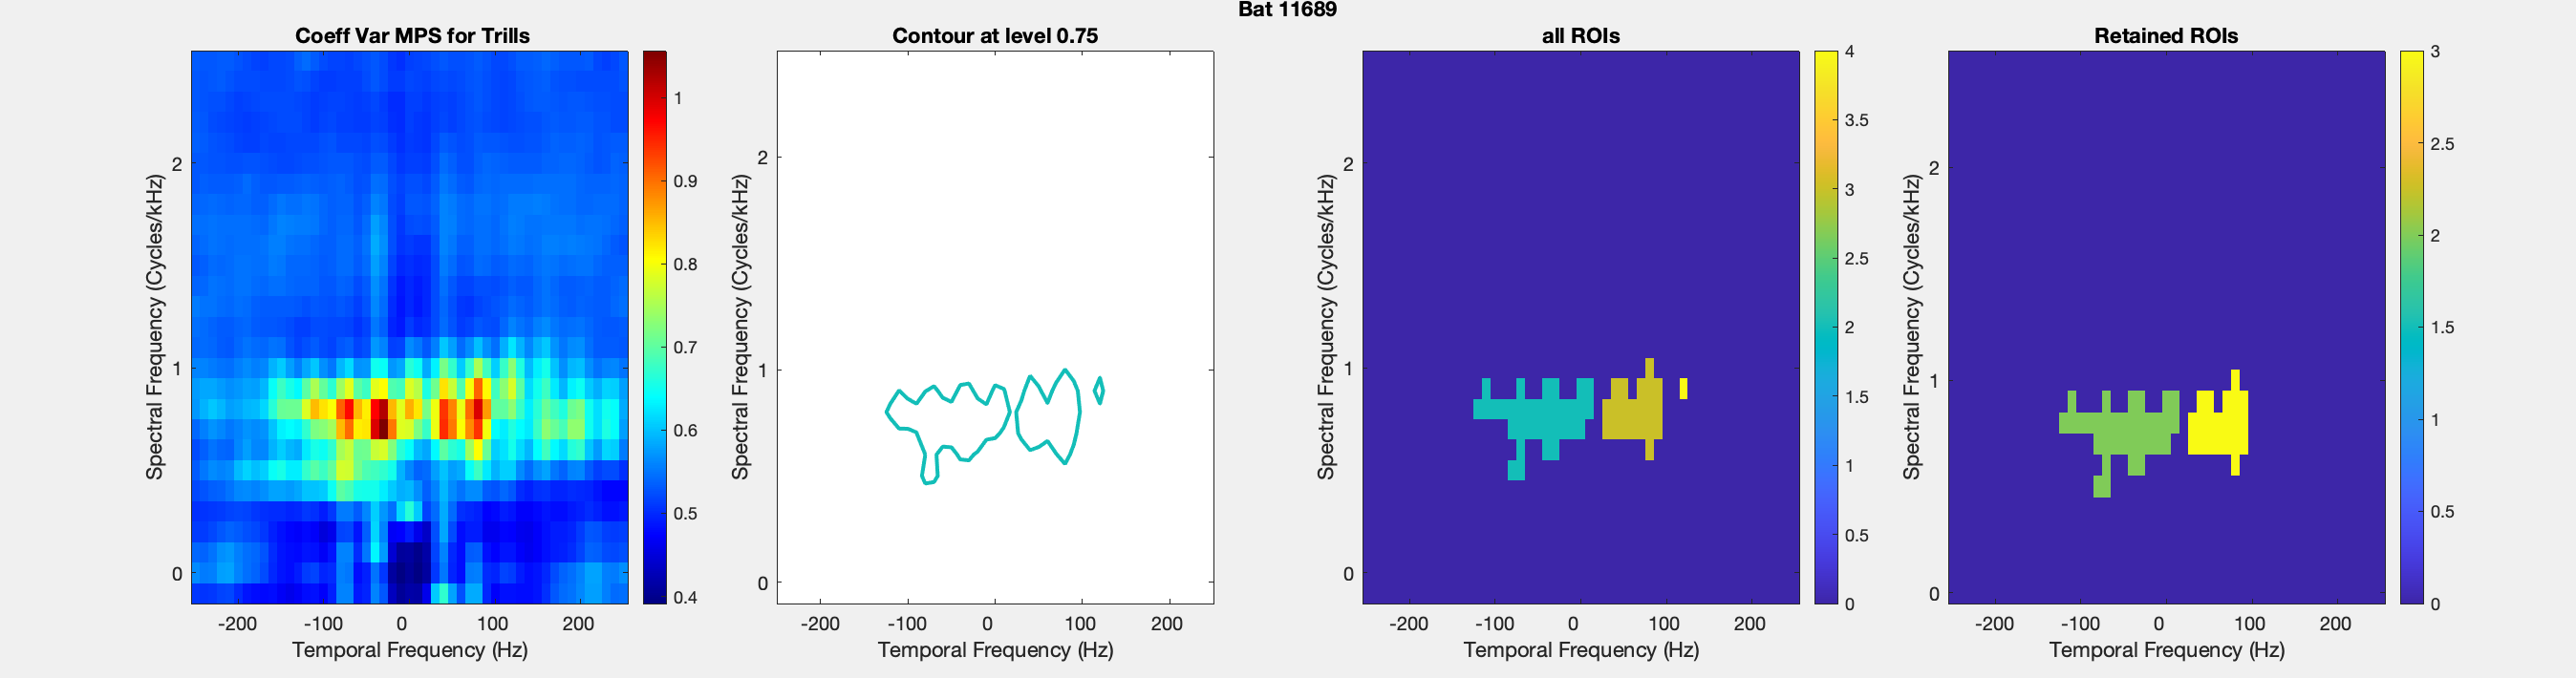

F=figure(5);
set(F,'Visible','on')
clf(F)
tiledlayout(1,4)
nexttile
[CVMPS4Contour, Wt_4plot, Wf_4plot] = plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0, [-0.1 2.5], [-250 250],nan,0.75);
title(' Coeff Var MPS for Trills')

nexttile
[Contour, Cplot] = contour(CVMPS4Contour,[Level Level]);
Cplot.LineWidth = 2;
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title(sprintf('Contour at level %.2f', Level))

% Identify the different contours
IndContour = find(Contour(1,:)==Level);
NpointsContour = Contour(2,IndContour);
[~,Ord] = sort(NpointsContour, 'descend');
ROI = cell(length(Ord),1);
ROI_map = zeros(size(CVMPS4Contour));
SeparateContour = cell(length(Ord),1);

for cont = 1:length(IndContour)
    SeparateContour{cont} = Contour(:,IndContour(Ord(cont))+(1:NpointsContour(Ord(cont))));
    ROI{cont} = poly2mask(SeparateContour{cont}(1,:), SeparateContour{cont}(2,:), size(CVMPS4Contour,1), size(CVMPS4Contour,2));
    ROI_map(logical(ROI{cont})) = cont+1;
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('all ROIs')

% Only keeping the larger ones
LargeContour = NpointsContour(Ord)>10;
ROI = ROI(LargeContour);
SeparateContour = SeparateContour(LargeContour);
SmallContour = find(~LargeContour);
for cont = 1:sum(~LargeContour)
    ROI_map(ROI_map==(SmallContour(cont)+1)) = 0;
end
% Restricting to positive values of frequencies
Wf_4plot2 = Wf_4plot(Wf_4plot>=0);
ROI_map = ROI_map(Wf_4plot>=0,:);
for cont = 1:length(ROI)
    ROI{cont} = ROI{cont}(Wf_4plot>=0,:);
    IndexWf = find(Wf_4plot>=0, 1);
    SeparateContour{cont}(2,:) = SeparateContour{cont}(2,:)-IndexWf;
    SeparateContour{cont} = SeparateContour{cont}(:,SeparateContour{cont}(2,:)>=0);
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot2*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot2*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('Retained ROIs')
Wf_ROI = Wf_4plot2;
Wt_ROI = Wt_4plot;
suplabel(sprintf('Bat %s', BatID), 't');

save(fullfile(Path2AllData,sprintf('%s_MPS_ROI_Trills_%s.mat', BatID, RecDevice)), 'BatAllTrillsMPS','Voc_wf','Voc_wt','ROI','Wf_ROI','Wt_ROI','SeparateContour','CVMPS4Contour','Level')

Other method to identify ROIs: clustering in the normalized MPS space and identification of regions of main differences -> In the end, Trills don't really cluster.. this is more a continuum than anything else, so not a good route to find the ROIs.... Code run last in March 2022 before the correcion on the cla identification. Not Run again on June-july 2022

% first focus our analysis on the center of the MPS that have the most
% power and variations
WfLim = [0 2.5]; %in cycles / kHz
WtLim = [-250 250]; %in Hz
Wf_i = logical((Voc_wf*10^3>=WfLim(1)).* (Voc_wf*10^3<=WfLim(2)));
Wt_i = logical((Voc_wt>=WtLim(1)).* (Voc_wt<=WtLim(2)));
MeanMPS_Focal = MeanMPS(Wf_i,Wt_i);
BatAllTrillsMPS_Focal = nan(size(BatAllTrillsMPS,1), numel(MeanMPS_Focal));
for jj=1:size(BatAllTrillsMPS,1)
    Local = reshape(BatAllTrillsMPS(jj,:)',length(Voc_wf), length(Voc_wt));
    Local = Local(Wf_i, Wt_i);
    Local(~ROI_map) = 0; % replace by zeros all the zones that are outside of main regions of variations
    BatAllTrillsMPS_Focal(jj,:) = reshape(Local,numel(Local),1)';
end
BatAllTrillsMPS_FocalNorm = BatAllTrillsMPS_Focal./repmat(reshape(MeanMPS_Focal,numel(MeanMPS_Focal),1)',size(BatAllTrillsMPS_Focal,1),1);

% Now run clustering algorithms varying the number of cluster. We want to
% have the minimum average distance within cluster and the maximum average
% distance of points to other cluster centroids
ClustNums = 2:15;
Sumd = cell(length(ClustNums),1);
D = cell(length(ClustNums),1);
KMIndex = cell(length(ClustNums),1);
AvWithin = nan(length(ClustNums),1);
AvBetween = nan(length(ClustNums),1);
for ii = 1:length(ClustNums)
    ClustNum = ClustNums(ii);
    fprintf(1, 'Kmeans %d/%d, k=%d\n', ii, length(ClustNums), ClustNum)
    [KMIndex{ii},~,Sumd{ii},D{ii}] = kmeans(BatAllTrillsMPS_FocalNorm, ClustNum, 'Distance',  'sqeuclidean','Replicates',10, 'Display','off');
    DistanceWithin = D{ii}(sub2ind(size(D{ii}),(1:size(D{ii},1))',KMIndex{ii}));
    ClusterSizes = accumarray (KMIndex{ii}, ones(length(KMIndex{ii}),1));
    PenaltySmallClusters = (length(KMIndex{ii})/ClustNum)./ClusterSizes;
    AvWithin(ii) = mean(DistanceWithin.*PenaltySmallClusters(KMIndex{ii}));
    DistanceBetween = D{ii};
    DistanceBetween(sub2ind(size(D{ii}),(1:size(D{ii},1))',KMIndex{ii})) = 0;
    AvBetween(ii) = sum(sum(DistanceBetween))/(numel(DistanceBetween)-length(KMIndex{ii}));
end

Kmeans 1/14, k=2
Kmeans 2/14, k=3
Kmeans 3/14, k=4
Kmeans 4/14, k=5
Kmeans 5/14, k=6
Kmeans 6/14, k=7
Kmeans 7/14, k=8
Kmeans 8/14, k=9
Kmeans 9/14, k=10
Kmeans 10/14, k=11
Kmeans 11/14, k=12
Kmeans 12/14, k=13
Kmeans 13/14, k=14
Kmeans 14/14, k=15


% Optimal number of clusters
fprintf(1,'***** Kmeans sqeuclidean******')

***** Kmeans sqeuclidean******

eva = evalclusters(BatAllTrillsMPS_FocalNorm,'kmeans','CalinskiHarabasz','KList',ClustNums)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 2203
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [331.8799 225.4371 172.9461 140.8614 119.1833 103.4570 90.9276 82.0856 73.6997 68.6034 62.2447 58.1545 54.5723 51.4061]
           OptimalK: 2


eva = evalclusters(BatAllTrillsMPS_FocalNorm,'kmeans','silhouette','KList',ClustNums)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 2203
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [0.1914 0.1088 0.0783 0.0394 0.0286 -0.0029 0.0209 0.0076 -0.0128 -0.0041 -0.0153 0.0042 -0.0046 -0.0183]
           OptimalK: 2


eva = evalclusters(BatAllTrillsMPS_FocalNorm,'kmeans','DaviesBouldin','KList',ClustNums)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 2203
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [2.8288 3.9401 4.5393 4.9138 5.1979 4.7633 5.6216 5.6591 5.2405 4.9754 4.7992 5.6465 4.9586 4.9905]
           OptimalK: 2


fprintf(1,'***** Kmeans correlation ******')

***** Kmeans correlation ******

eva = evalclusters(BatAllTrillsMPS_FocalNorm,'kmeans','silhouette','KList',ClustNums, 'Distance', 'correlation')

eva =   SilhouetteEvaluation with properties:

    NumObservations: 2203
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [0.2086 0.1027 0.0700 0.0626 0.0507 0.0470 0.0431 0.0463 0.0430 0.0402 0.0392 0.0410 0.0398 0.0355]
           OptimalK: 2


fprintf(1,'***** Linkage ******')
eva = evalclusters(BatAllTrillsMPS_FocalNorm,'linkage','silhouette','KList',ClustNums)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 2203
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [0.2151 0.0291 0.0390 -0.0102 -0.0071 -0.0132 -0.0111 -0.0157 -0.0358 -0.0340 -0.0329 -0.0317 -0.0309 -0.0393]
           OptimalK: 2


% My own metrics
figure()
yyaxis left
plot(ClustNums,AvBetween,'-k', 'LineWidth',2)
hold on
plot(ClustNums,AvWithin,':k', 'LineWidth',2)
legend('Between', 'Within')
xlabel('Number of clusters in KMeans')
ylabel('Average distance of each point to centroids')
yyaxis right
plot(ClustNums,AvBetween./AvWithin, 'r', 'LineWidth',2 )
ylabel('Between/Within')
title('Clustering of the data across number of clusters')
hold off

ClustNumOpt = ClustNums(AvBetween./AvWithin == max(AvBetween./AvWithin));
fprintf(1, '%d is the optimal number of clusters', ClustNumOpt)

15 is the optimal number of clusters

accumarray (KMIndex{ClustNums == ClustNumOpt}, ones(length(KMIndex{ClustNums == ClustNumOpt}),1))

% Run PCA to see how varied the MPS are in a small space
PercVar = 80;
figure()
[PC_mps,Score_mps,~, ~, VarExpl_mps,~] = pca(BatAllTrillsMPS_FocalNorm);
scatter(Score_mps(:,1),Score_mps(:,2))
xlabel('PC1 MPS')
ylabel('PC2 MPS')

figure()
plot(cumsum(VarExpl_mps), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_mps)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_mps)>PercVar,1)))
hold off
title('MPS')

## Same calculations for second Bat

Gather Time varying PAF For second Bat

% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
StimDuraMax = 300; % duration in ms of trills according to script Explore Calls 97% of trills are within that time window for both vocalizer bats
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{2};
ListCellsGVBatID = ListCellsGV(contains(ListCellsGV,BatID));
NC = length(ListCellsGVBatID);
Trills_fund = cell(1,NC);
Trills_sal = cell(1,NC);
Trills_amp = cell(1,NC);
Trills_specMean = cell(1,NC);
Trills_formDisp = cell(1,NC);
Trills_spectroPiezoto = cell(1,NC);
Trills_spectroPiezofo = cell(1,NC);
Trills_spectroPiezo = cell(1,NC);
Trills_spectroMicto = cell(1,NC);
Trills_spectroMicfo = cell(1,NC);
Trills_spectroMic = cell(1,NC);
SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:length(ListCellsGVBatID)
    [~,Filecc1] = fileparts(ListCellsGVBatID{cc});
    if cc>1 
        [~,Filecc2] = fileparts(ListCellsGVBatID{cc-1});
        if strcmp(Filecc1(1:14),Filecc2(1:14))
            % we have already gather these data, skip
            continue
        end
    end
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, length(ListCellsGVBatID))
    Cell = load(ListCellsGVBatID{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') );
        
    end
    % initialize the matrix of acoustic values with zeros
    Trills_fund{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_sal{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_amp{cc} = zeros(StimDuraMax,length(IndVoc));
    Trills_specMean{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_formDisp{cc} = nan(StimDuraMax,length(IndVoc));
    Trills_spectroPiezo{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    Trills_spectroMic{cc} = cell(1, length(IndVoc));
    Trills_spectroMicto{cc} = cell(1, length(IndVoc));
    Trills_spectroMicfo{cc} = cell(1, length(IndVoc));

    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:length(IndVoc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        if StimDur<=StimDuraMax
            Trills_fund{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            Trills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            Trills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            Trills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            Trills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        else
            TempFund = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            Trills_fund{cc}(:,Nstim) = TempFund(1:StimDuraMax);
            TempSal = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            Trills_sal{cc}(:,Nstim) = TempSal(1:StimDuraMax);
            TempAmp = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            Trills_amp{cc}(:,Nstim) = TempAmp(1:StimDuraMax);
            TempSpecMean = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            Trills_specMean{cc}(:,Nstim) = TempSpecMean(1:StimDuraMax);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            TempFormDisp = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
            Trills_formDisp{cc}(:,Nstim) = TempFormDisp(1:StimDuraMax);
        end
        
        Trills_spectroPiezo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.spectro;
        Trills_spectroPiezoto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.to;
        Trills_spectroPiezofo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.fo;
        Trills_spectroMic{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.spectro;
        Trills_spectroMicto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.to;
        Trills_spectroMicfo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.fo;

    end
end

Cell 1/476
Cell 16/476
Cell 28/476
Cell 33/476
Cell 40/476
Cell 42/476
Cell 53/476
Cell 67/476
Cell 78/476
Cell 91/476
Cell 107/476
Cell 116/476
Cell 131/476
Cell 155/476
Cell 173/476
Cell 186/476
Cell 199/476
Cell 219/476
Cell 236/476
Cell 252/476
Cell 264/476
Cell 288/476
Cell 303/476
Cell 324/476
Cell 338/476
Cell 359/476
Cell 376/476
Cell 389/476
Cell 407/476
Cell 425/476
Cell 441/476
Cell 455/476
Cell 465/476


Trills_fund_mat = [Trills_fund{:}]';
Trills_sal_mat = [Trills_sal{:}]';
Trills_amp_mat = [Trills_amp{:}]';
Trills_specMean_mat = [Trills_specMean{:}]';
Trills_formDisp_mat = [Trills_formDisp{:}]';

% replace nan values by 0
% Trills_fund_mat(isnan(Trills_fund_mat)) = 0;
% Trills_sal_mat(isnan(Trills_sal_mat)) = 0;
% Trills_amp_mat(isnan(Trills_amp_mat)) = 0;
% Trills_specMean_mat(isnan(Trills_specMean_mat)) = 0;
% Trills_formDisp_mat(isnan(Trills_formDisp_mat)) = 0;


Plot the average vocalization

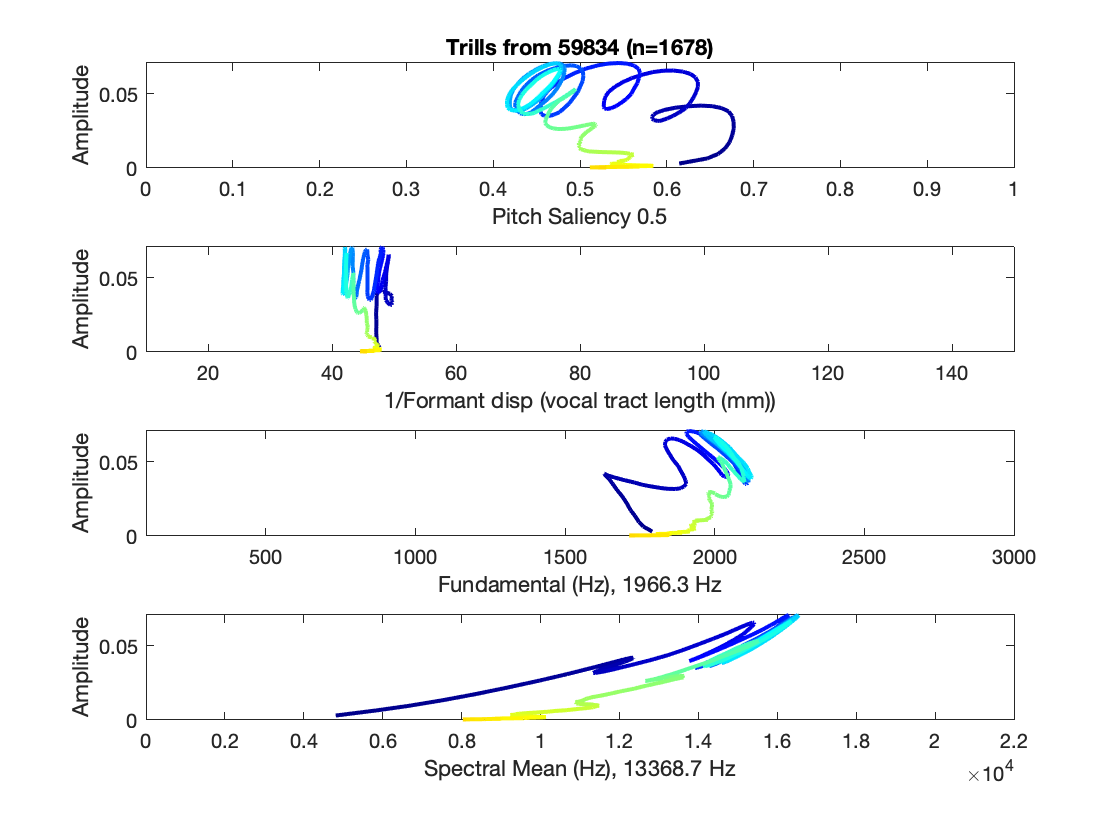



HalfSpan = (Span-1)/2;
% Plot the pitch saliency vs amplitude on microphone
figure()
subplot(4,1,1)
hold off
Saliency = mean(Trills_sal_mat, 'omitnan');
Amplitude = mean(Trills_amp_mat, 'omitnan');
TimeSound = 1:size(Trills_sal_mat,2);
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
xlabel(sprintf('Pitch Saliency %.1f', mean(Saliency)))
ylabel('Amplitude')
title(sprintf('Trills from %s (n=%d)', BatID, size(Trills_amp_mat,1)))
hold off

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
hold off
FormantDisp = mean(Trills_formDisp_mat, 'omitnan');
nx = length(FormantDisp);


for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
xlabel('1/Formant disp (vocal tract length (mm))')
ylabel('Amplitude')
hold off

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
hold off
SoundFund = mean(Trills_fund_mat, 'omitnan');
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund, 'omitnan')))
    set(gca,'XLim',[100 3000])
end
hold off

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
hold off
SoundSpecMean = mean(Trills_specMean_mat, 'omitnan');
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
    set(gca,'XLim',[0 22000])
end
hold off

RecDevice = 'Mic'; %set to 'Mic' or 'Piezo'
AllMPSFiles = dir(fullfile(Path2AllData, ['*_MPS' RecDevice '.mat']));
AllMPSFiles = struct2cell(AllMPSFiles);
AllMPSFiles = AllMPSFiles(1,:)';
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{2};
BatMPSFiles = AllMPSFiles(contains(AllMPSFiles, BatID));
BatAllTrillsMPS = cell(1,length(BatMPSFiles));
for ff=1:length(BatMPSFiles)
    load(fullfile(Path2AllData, BatMPSFiles{ff}), 'Voc_mps', 'Voc_wt', 'Voc_wf','IndVoc', 'Voc_what', 'Voc_who');
    IndTrills = find(contains(Voc_what, 'Tr').* contains(Voc_who, 'self'));
    NTrills = length(IndTrills);
    BatAllTrillsMPS{ff} = nan(numel(Voc_mps{1}), NTrills);
    for tt=1:NTrills
        BatAllTrillsMPS{ff}(:,tt) = reshape(Voc_mps{IndTrills(tt)}, numel(Voc_mps{1}),1);
    end
end
BatAllTrillsMPS = [BatAllTrillsMPS{:}]';

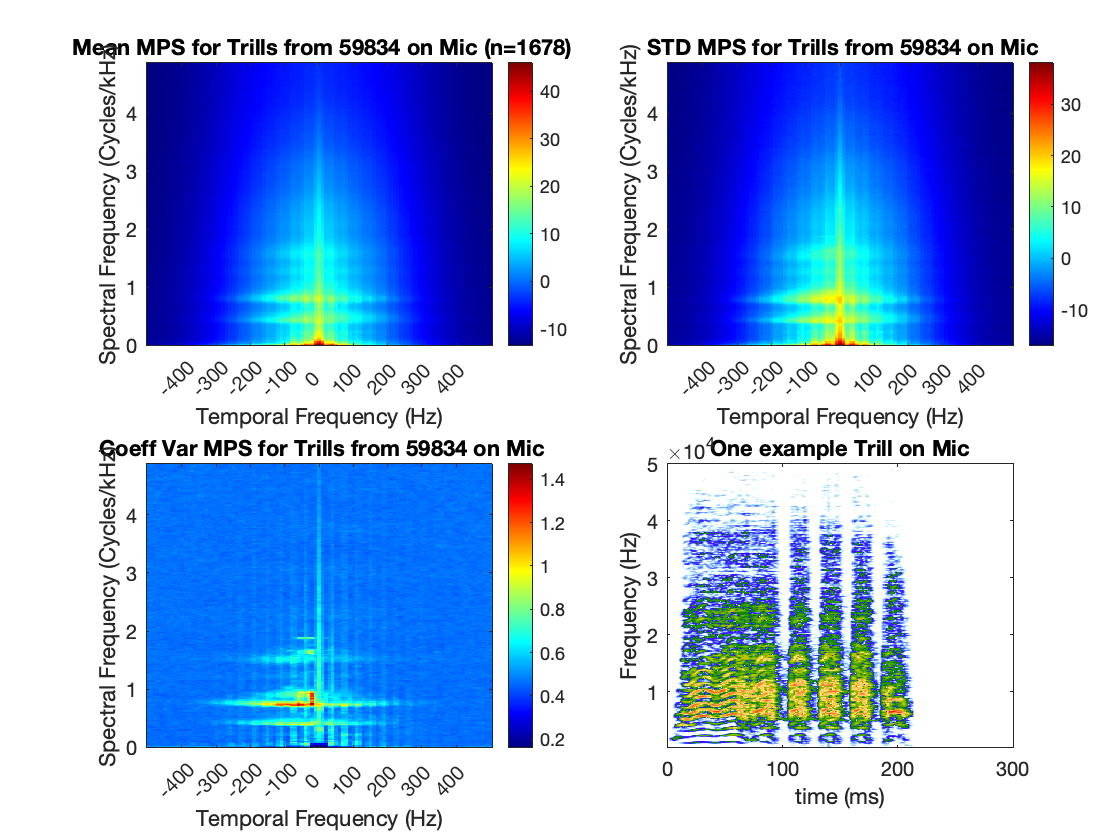

% plot the average and the STD mps now!
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(BatAllTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(MeanMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' Mean MPS for Trills from %s on %s (n=%d)', BatID, RecDevice, size(BatAllTrillsMPS,1)))

nexttile
STDMPS = reshape(std(BatAllTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(STDMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' STD MPS for Trills from %s on %s', BatID, RecDevice))

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0);
title(sprintf(' Coeff Var MPS for Trills from %s on %s',BatID, RecDevice))

% One spectrogram example
nexttile
if strcmp(RecDevice , 'Mic')
    DayExample = find(~cellfun('isempty', Trills_spectroMic),1,'last');
    plot_spectro(Trills_spectroMic{DayExample}{1},DBNOISE, Trills_spectroMicto{DayExample}{1}, Trills_spectroMicfo{DayExample}{1}, 100, 50000,300)
elseif strcmp(RecDevice, 'Piezo')
    DayExample = find(~cellfun('isempty', Trills_spectroPiezo),1,'last');
    plot_spectro(Trills_spectroPiezo{DayExample}{1},DBNOISE, Trills_spectroPiezoto{DayExample}{1}, Trills_spectroPiezofo{DayExample}{1}, 100, 20000,300)
end
title(sprintf('One example Trill on %s', RecDevice))

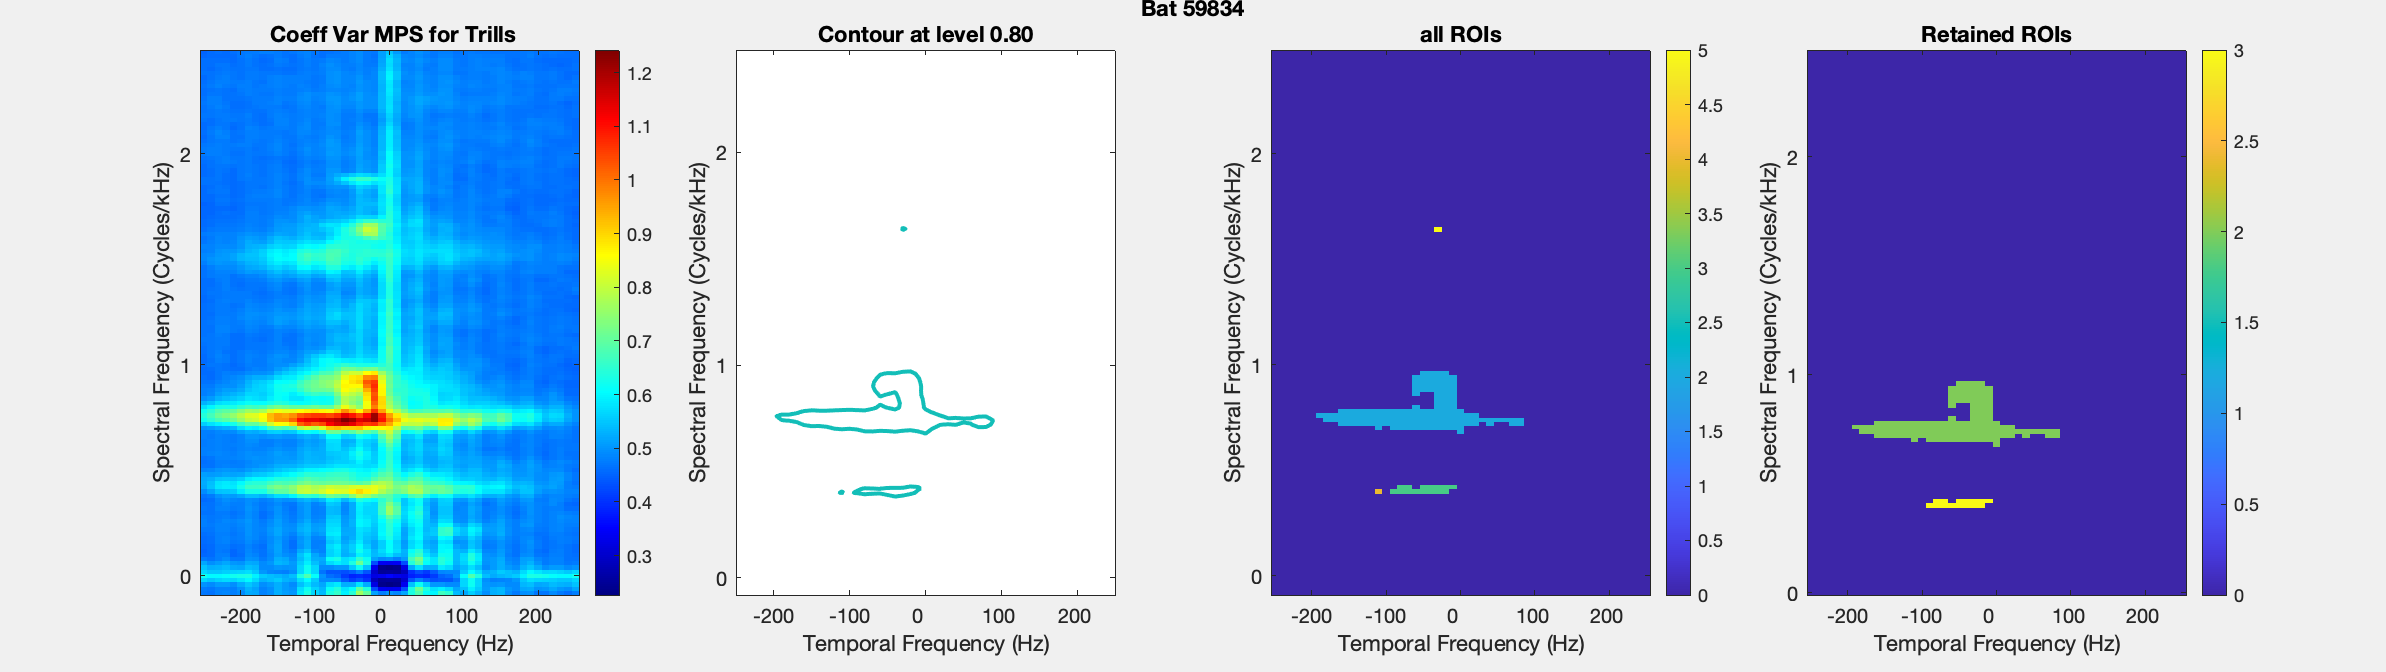

% Identify ROI in the Coeff Var MPS
% Level = max(max(VarMPS))/2; =0.64 too low!!
Level = 0.8; %0.8 for Piezo
F=figure(6);
set(F,'Visible','on')
clf(F)
tiledlayout(1,4)
nexttile
[CVMPS4Contour, Wt_4plot, Wf_4plot] = plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0, [-0.1 2.5], [-250 250],nan,0.75);
title(' Coeff Var MPS for Trills')

nexttile
[Contour, Cplot] = contour(CVMPS4Contour,[Level Level]);
Cplot.LineWidth = 2;
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title(sprintf('Contour at level %.2f', Level))

% Identify the different contours
IndContour = find(Contour(1,:)==Level);
NpointsContour = Contour(2,IndContour);
[~,Ord] = sort(NpointsContour, 'descend');
ROI = cell(length(Ord),1);
ROI_map = zeros(size(CVMPS4Contour));
SeparateContour = cell(length(Ord),1);

for cont = 1:length(IndContour)
    SeparateContour{cont} = Contour(:,IndContour(Ord(cont))+(1:NpointsContour(Ord(cont))));
    ROI{cont} = poly2mask(SeparateContour{cont}(1,:), SeparateContour{cont}(2,:), size(CVMPS4Contour,1), size(CVMPS4Contour,2));
    ROI_map(logical(ROI{cont})) = cont+1;
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('all ROIs')

% Only keeping the larger ones
LargeContour = NpointsContour(Ord)>10;
ROI = ROI(LargeContour);
SeparateContour = SeparateContour(LargeContour);
SmallContour = find(~LargeContour);
for cont = 1:sum(~LargeContour)
    ROI_map(ROI_map==(SmallContour(cont)+1)) = 0;
end


% Restricting to positive values of frequencies
Wf_4plot2 = Wf_4plot(Wf_4plot>=0);
ROI_map = ROI_map(Wf_4plot>=0,:);
for cont = 1:length(ROI)
    ROI{cont} = ROI{cont}(Wf_4plot>=0,:);
    IndexWf = find(Wf_4plot>=0, 1);
    SeparateContour{cont}(2,:) = SeparateContour{cont}(2,:)-IndexWf;
    SeparateContour{cont} = SeparateContour{cont}(:,SeparateContour{cont}(2,:)>=0);
end

nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot2*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot2*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('Retained ROIs')
Wf_ROI = Wf_4plot2;
Wt_ROI = Wt_4plot;
suplabel(sprintf('Bat %s', BatID), 't');

save(fullfile(Path2AllData,sprintf('%s_MPS_ROI_Trills_%s.mat', BatID, RecDevice)), 'BatAllTrillsMPS','Voc_wf','Voc_wt','ROI','SeparateContour','Wf_ROI','Wt_ROI','CVMPS4Contour','Level')

## Calculations for non-Trills Bat2

Gather Time varying PAF For first Bat

% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
StimDuraMax = 300; % duration in ms of trills according to script Explore Calls 97% of trills are within that time window for both vocalizer bats
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{2};
ListCellsGVBatID = ListCellsGV(contains(ListCellsGV,BatID));
NC = length(ListCellsGVBatID);
NonTrills_fund = cell(1,NC);
NonTrills_sal = cell(1,NC);
NonTrills_amp = cell(1,NC);
NonTrills_specMean = cell(1,NC);
NonTrills_formDisp = cell(1,NC);
NonTrills_spectroPiezoto = cell(1,NC);
NonTrills_spectroPiezofo = cell(1,NC);
NonTrills_spectroPiezo = cell(1,NC);
NonTrills_spectroMicto = cell(1,NC);
NonTrills_spectroMicfo = cell(1,NC);
NonTrills_spectroMic = cell(1,NC);
SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:length(ListCellsGVBatID)
    [~,Filecc1] = fileparts(ListCellsGVBatID{cc});
    if cc>1 
        [~,Filecc2] = fileparts(ListCellsGVBatID{cc-1});
        if strcmp(Filecc1(1:14),Filecc2(1:14))
            % we have already gather these data, skip
            continue
        end
    end
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, length(ListCellsGVBatID))
    Cell = load(ListCellsGVBatID{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(logical(~contains(Cell.What, 'VocTr') .* ~contains(Cell.What, 'VocNa')) .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') );
        if isempty(IndVoc)
            continue
        end
    end
    % initialize the matrix of acoustic values with nan or zeros 
    NonTrills_fund{cc} = nan(StimDuraMax,length(IndVoc));
    NonTrills_sal{cc} = nan(StimDuraMax,length(IndVoc));
    NonTrills_amp{cc} = zeros(StimDuraMax,length(IndVoc));
    NonTrills_specMean{cc} = nan(StimDuraMax,length(IndVoc));
    NonTrills_formDisp{cc} = nan(StimDuraMax,length(IndVoc));
    NonTrills_spectroPiezo{cc} = cell(1, length(IndVoc));
    NonTrills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    NonTrills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMic{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMicto{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMicfo{cc} = cell(1, length(IndVoc));

    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:length(IndVoc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        if StimDur<=StimDuraMax
            if ~isempty(Cell.BioSound{IndVoc(Nstim),2}.f0)
                NonTrills_fund{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            else
                NonTrills_fund{cc}(1:StimDur,Nstim) = nan(length(StimDur),1);
            end
            NonTrills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            NonTrills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            NonTrills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            NonTrills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        else
            TempFund = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            NonTrills_fund{cc}(:,Nstim) = TempFund(1:StimDuraMax);
            TempSal = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
            NonTrills_sal{cc}(:,Nstim) = TempSal(1:StimDuraMax);
            TempAmp = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
            NonTrills_amp{cc}(:,Nstim) = TempAmp(1:StimDuraMax);
            TempSpecMean = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
            NonTrills_specMean{cc}(:,Nstim) = TempSpecMean(1:StimDuraMax);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            TempFormDisp = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
            NonTrills_formDisp{cc}(:,Nstim) = TempFormDisp(1:StimDuraMax);
        end
        
        NonTrills_spectroPiezo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.spectro;
        NonTrills_spectroPiezoto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.to;
        NonTrills_spectroPiezofo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.fo;
        NonTrills_spectroMic{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.spectro;
        NonTrills_spectroMicto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.to;
        NonTrills_spectroMicfo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.fo;

    end
end

Cell 1/476
Cell 16/476
Cell 28/476
Cell 33/476
Cell 40/476
Cell 42/476
Cell 53/476
Cell 67/476
Cell 78/476
Cell 91/476
Cell 107/476
Cell 116/476
Cell 131/476
Cell 155/476
Cell 173/476
Cell 186/476
Cell 199/476
Cell 219/476
Cell 236/476
Cell 252/476
Cell 264/476
Cell 288/476
Cell 303/476
Cell 324/476
Cell 338/476
Cell 359/476
Cell 376/476
Cell 389/476
Cell 407/476
Cell 425/476
Cell 441/476
Cell 455/476
Cell 465/476


NonTrills_fund_mat = [NonTrills_fund{:}]';
NonTrills_sal_mat = [NonTrills_sal{:}]';
NonTrills_amp_mat = [NonTrills_amp{:}]';
NonTrills_specMean_mat = [NonTrills_specMean{:}]';
NonTrills_formDisp_mat = [NonTrills_formDisp{:}]';

% replace nan values by 0
% NonTrills_fund_mat(isnan(NonTrills_fund_mat)) = 0;
% NonTrills_sal_mat(isnan(NonTrills_sal_mat)) = 0;
% NonTrills_amp_mat(isnan(NonTrills_amp_mat)) = 0;
% NonTrills_specMean_mat(isnan(NonTrills_specMean_mat)) = 0;
% NonTrills_formDisp_mat(isnan(NonTrills_formDisp_mat)) = 0;


Plot the average vocalization

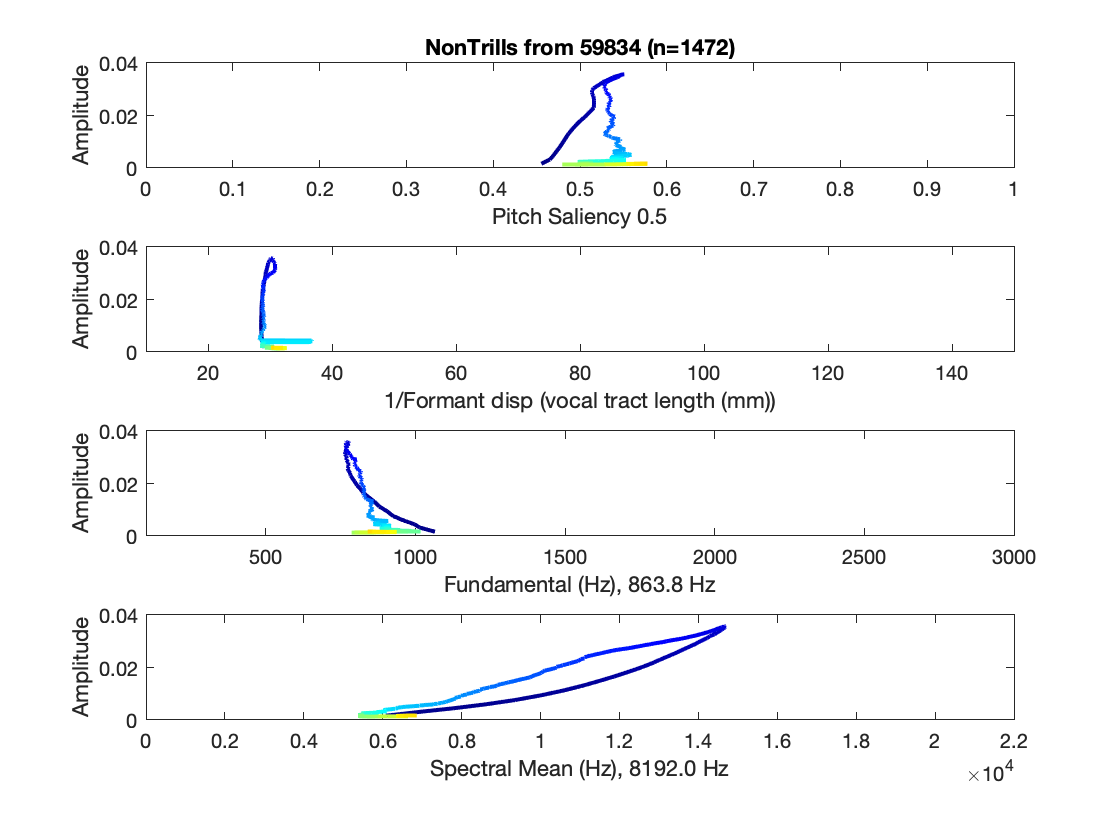



HalfSpan = (Span-1)/2;
% Plot the pitch saliency vs amplitude on microphone
figure()
subplot(4,1,1)
hold off
Saliency = mean(NonTrills_sal_mat, 'omitnan');
Amplitude = mean(NonTrills_amp_mat,'omitnan');
TimeSound = 1:size(NonTrills_sal_mat,2);
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
xlabel(sprintf('Pitch Saliency %.1f', mean(Saliency)))
ylabel('Amplitude')
title(sprintf('NonTrills from %s (n=%d)', BatID, size(NonTrills_amp_mat,1)))
hold off

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
hold off
FormantDisp = mean(NonTrills_formDisp_mat,'omitnan');
nx = length(FormantDisp);


for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
xlabel('1/Formant disp (vocal tract length (mm))')
ylabel('Amplitude')
hold off

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
hold off
SoundFund = mean(NonTrills_fund_mat,'omitnan');
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund, 'omitnan')))
    set(gca,'XLim',[100 3000])
end
hold off

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
hold off
SoundSpecMean = mean(NonTrills_specMean_mat,'omitnan');
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
    set(gca,'XLim',[0 22000])
end
hold off

RecDevice = 'Mic'; %set to 'Mic' or 'Piezo'
AllMPSFiles = dir(fullfile(Path2AllData, ['*_MPS' RecDevice '.mat']));
AllMPSFiles = struct2cell(AllMPSFiles);
AllMPSFiles = AllMPSFiles(1,:)';
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{2};
BatMPSFiles = AllMPSFiles(contains(AllMPSFiles, BatID));
BatAllNonTrillsMPS = cell(1,length(BatMPSFiles));
for ff=1:length(BatMPSFiles)
    load(fullfile(Path2AllData, BatMPSFiles{ff}), 'Voc_mps', 'Voc_wt', 'Voc_wf','IndVoc', 'Voc_what', 'Voc_who');
    IndNonTrills = find(contains(Voc_what, 'Ba').* contains(Voc_who, 'self'));
    NNonTrills = length(IndNonTrills);
    BatAllNonTrillsMPS{ff} = nan(numel(Voc_mps{1}), NNonTrills);
    for tt=1:NNonTrills
        BatAllNonTrillsMPS{ff}(:,tt) = reshape(Voc_mps{IndNonTrills(tt)}, numel(Voc_mps{1}),1);
    end
end
BatAllNonTrillsMPS = [BatAllNonTrillsMPS{:}]';

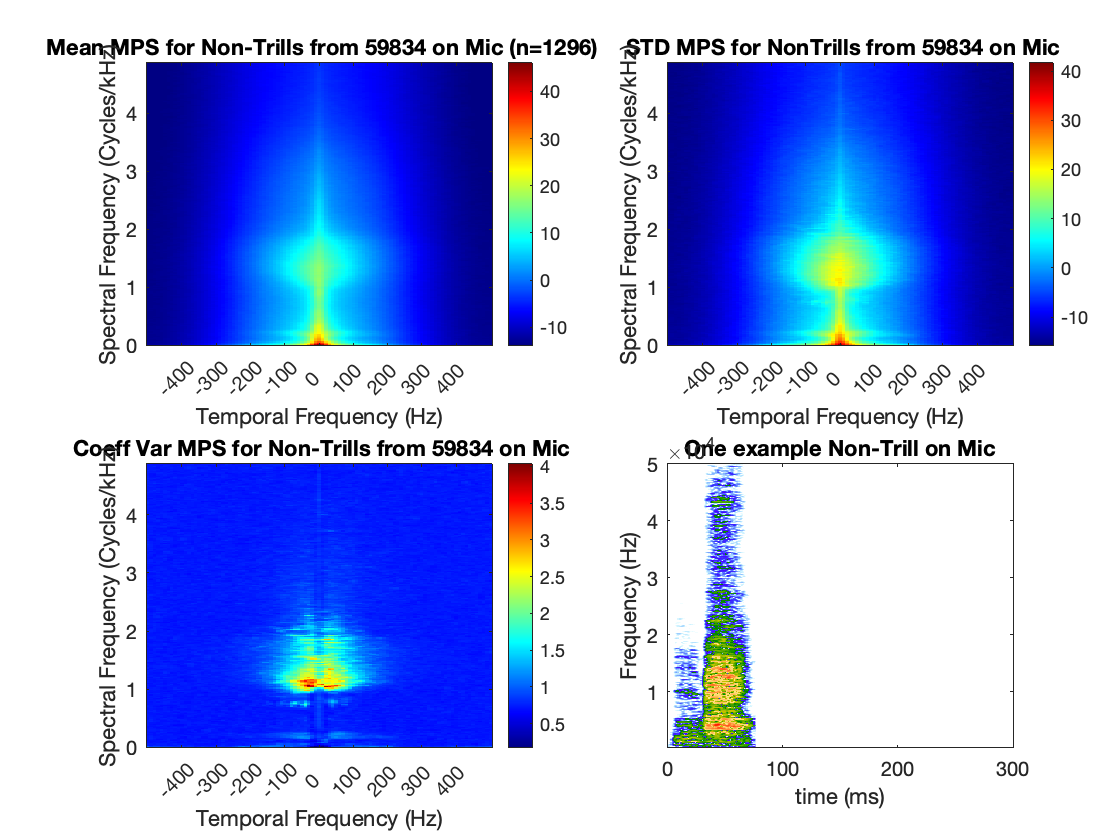

% plot the average and the STD mps now!
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(BatAllNonTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(MeanMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' Mean MPS for Non-Trills from %s on %s (n=%d)', BatID, RecDevice, size(BatAllNonTrillsMPS,1)))

nexttile
STDMPS = reshape(std(BatAllNonTrillsMPS),length(Voc_wf), length(Voc_wt));
plot_mps(STDMPS, Voc_wf, Voc_wt, DBNOISE);
title(sprintf(' STD MPS for NonTrills from %s on %s', BatID, RecDevice))

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0);
title(sprintf(' Coeff Var MPS for Non-Trills from %s on %s',BatID, RecDevice))

% One spectrogram example
nexttile
if strcmp(RecDevice , 'Mic')
    DayExample = find(~cellfun('isempty', NonTrills_spectroMic),1,'last');
    plot_spectro(NonTrills_spectroMic{DayExample}{1},DBNOISE, NonTrills_spectroMicto{DayExample}{1}, NonTrills_spectroMicfo{DayExample}{1}, 100, 50000,300)
elseif strcmp(RecDevice, 'Piezo')
    DayExample = find(~cellfun('isempty', NonTrills_spectroPiezo),1,'last');
    plot_spectro(NonTrills_spectroPiezo{DayExample}{1},DBNOISE, NonTrills_spectroPiezoto{DayExample}{1}, NonTrills_spectroPiezofo{DayExample}{1}, 100, 20000,300)
end
title(sprintf('One example Non-Trill on %s', RecDevice))

% Identify ROI in the Coeff Var MPS
if strcmp(RecDevice, 'Mic')
    Level = max(max(VarMPS)).*0.55 % *0.55
elseif strcmp(RecDevice, 'Piezo')
    Level = max(max(VarMPS)).*0.4 % *0.55
end

Level = 2.2177

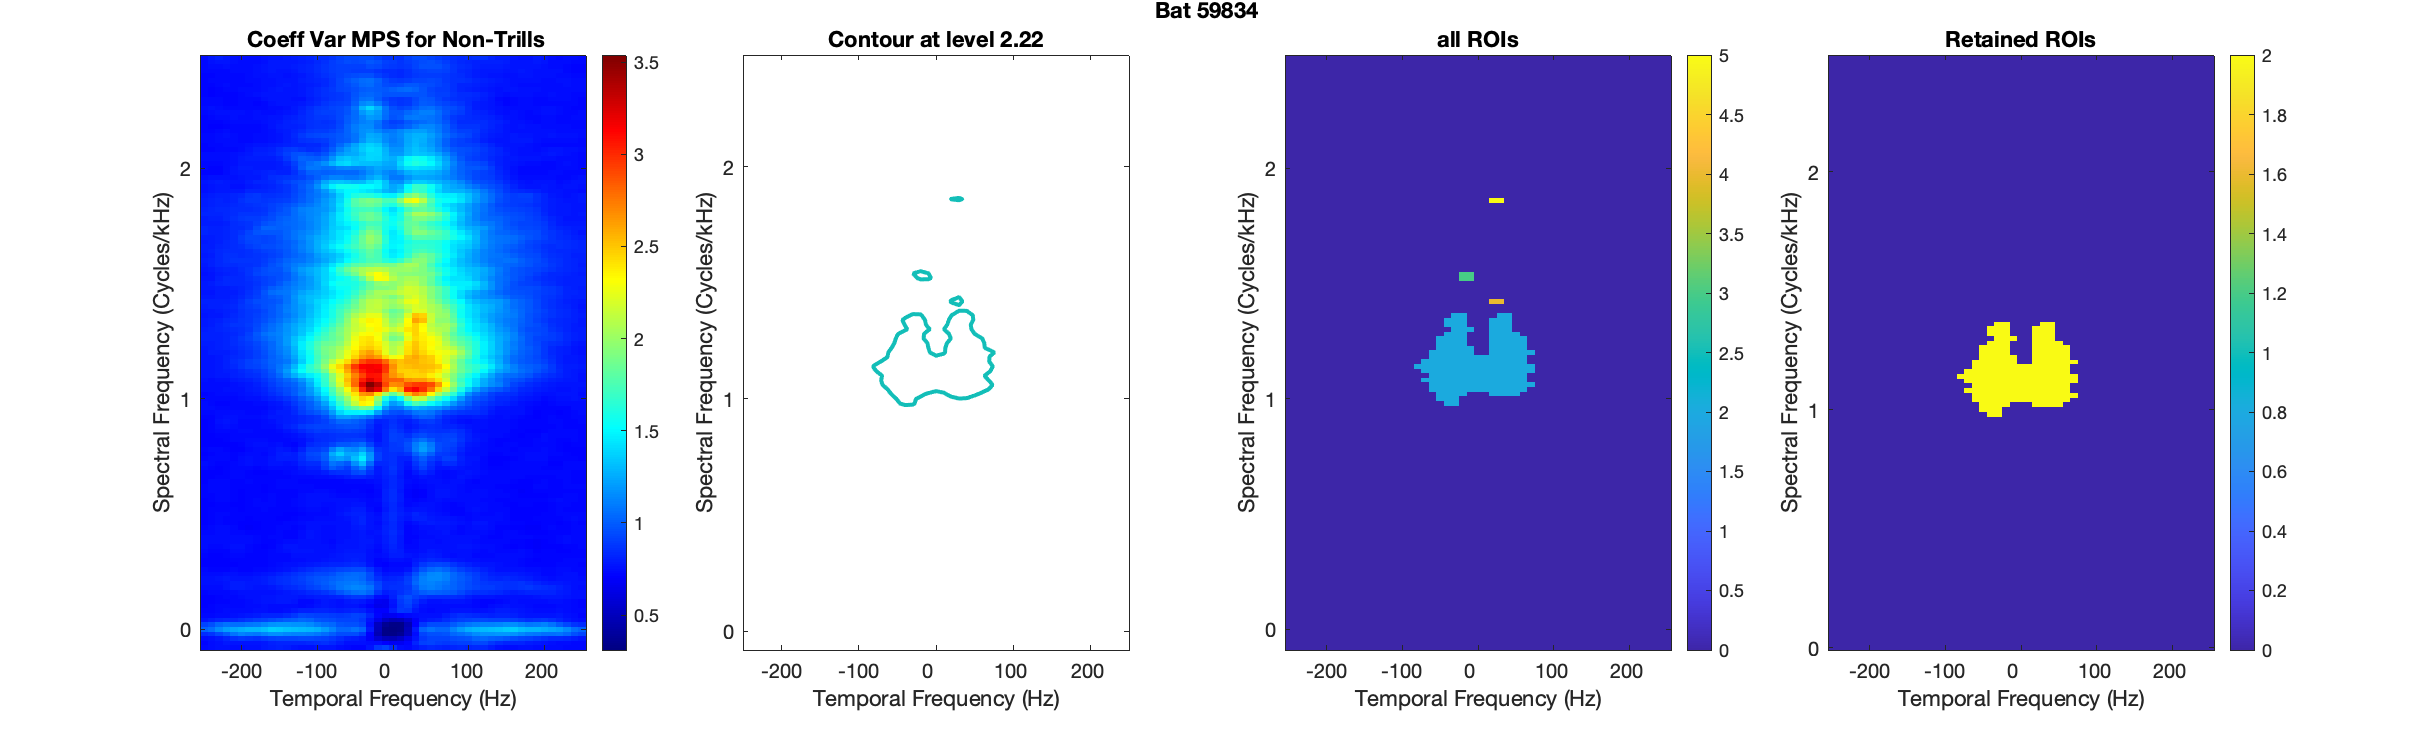

F=figure(6);
set(F,'Visible','on')
clf(F)
tiledlayout(1,4)
nexttile
[CVMPS4Contour, Wt_4plot, Wf_4plot] = plot_mps(VarMPS, Voc_wf, Voc_wt, DBNOISE,0, [-0.1 2.5], [-250 250],nan,0.75);
title(' Coeff Var MPS for Non-Trills')

nexttile
[Contour, Cplot] = contour(CVMPS4Contour,[Level Level]);
Cplot.LineWidth = 2;
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title(sprintf('Contour at level %.2f', Level))

% Identify the different contours
IndContour = find(Contour(1,:)==Level);
NpointsContour = Contour(2,IndContour);
[~,Ord] = sort(NpointsContour, 'descend');
ROI = cell(length(Ord),1);
ROI_map = zeros(size(CVMPS4Contour));
SeparateContour = cell(length(Ord),1);

for cont = 1:length(IndContour)
    SeparateContour{cont} = Contour(:,IndContour(Ord(cont))+(1:NpointsContour(Ord(cont))));
    ROI{cont} = poly2mask(SeparateContour{cont}(1,:), SeparateContour{cont}(2,:), size(CVMPS4Contour,1), size(CVMPS4Contour,2));
    ROI_map(logical(ROI{cont})) = cont+1;
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('all ROIs')

% Only keeping the larger ones
LargeContour = NpointsContour(Ord)>10;
ROI = ROI(LargeContour);
SeparateContour = SeparateContour(LargeContour);
SmallContour = find(~LargeContour);
for cont = 1:sum(~LargeContour)
    ROI_map(ROI_map==(SmallContour(cont)+1)) = 0;
end


% Restricting to positive values of frequencies
Wf_4plot2 = Wf_4plot(Wf_4plot>=0);
ROI_map = ROI_map(Wf_4plot>=0,:);
for cont = 1:length(ROI)
    ROI{cont} = ROI{cont}(Wf_4plot>=0,:);
    IndexWf = find(Wf_4plot>=0, 1);
    SeparateContour{cont}(2,:) = SeparateContour{cont}(2,:)-IndexWf;
    SeparateContour{cont} = SeparateContour{cont}(:,SeparateContour{cont}(2,:)>=0);
end

nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot2*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot2*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('Retained ROIs')
Wf_ROI = Wf_4plot2;
Wt_ROI = Wt_4plot;
suplabel(sprintf('Bat %s', BatID), 't');

save(fullfile(Path2AllData,sprintf('%s_MPS_ROI_NonTrills_%s.mat', BatID, RecDevice)), 'BatAllNonTrillsMPS','Voc_wf','Voc_wt','ROI','SeparateContour','Wf_ROI','Wt_ROI','CVMPS4Contour','Level')

## Gathering tme average acoustic features (PAF)

% Obtain a large matrix of all single Trill time average pitch, amplitude, saliency etc...
VocOperantID = {'11689', '59834'};
BatID = VocOperantID{1};
ListCellsGVBatID = ListCellsGV(contains(ListCellsGV,BatID));
NC = length(ListCellsGVBatID);
PAF.type = cell(1,NC);
% parameters that pertains to fundamental
PAF.meanfund = cell(1,NC);
PAF.cvfund = cell(1,NC);
PAF.minfund = cell(1,NC);
PAF.maxfund = cell(1,NC);
% Parameters of pitch saliency
PAF.meansal = cell(1,NC);
PAF.stdsal = cell(1,NC);
% paramters of sound amplitude
PAF.meanamp = cell(1,NC);
PAF.rms = cell(1,NC);
PAF.stdamp = cell(1,NC);
% Parameters of sound spectrum
PAF.meanspect = cell(1,NC);
PAF.stdspect = cell(1,NC);
PAF.entropyspect = cell(1,NC);
PAF.kurtspect = cell(1,NC);
PAF.skewspect = cell(1,NC);
PAF.q1 = cell(1,NC);
PAF.q2 = cell(1,NC);
PAF.q3 = cell(1,NC);
% Parameters of temporal dynamic
PAF.meantime = cell(1,NC);
PAF.stdtime = cell(1,NC);
PAF.entropytime = cell(1,NC);
PAF.kurttime = cell(1,NC);
PAF.skewtime = cell(1,NC);


SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:length(ListCellsGVBatID)
    [~,Filecc1] = fileparts(ListCellsGVBatID{cc});
    if cc>1 
        [~,Filecc2] = fileparts(ListCellsGVBatID{cc-1});
        if strcmp(Filecc1(1:14),Filecc2(1:14))
            % we have already gather these data, skip
            continue
        end
    end
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, length(ListCellsGVBatID))
    Cell = load(ListCellsGVBatID{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'Voc') .* ~contains(Cell.What, 'VocNa') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') );
        
    end
    % initialize the matrix of acoustic values with nan or zeros
    % parameters that pertains to fundamental
    PAF.meanfund{cc} = nan(1,length(IndVoc));
    PAF.cvfund{cc} = nan(1,length(IndVoc));
    PAF.minfund{cc} = nan(1,length(IndVoc));
    PAF.maxfund{cc} = nan(1,length(IndVoc));
    % Parameters of pitch saliency
    PAF.meansal{cc} = nan(1,length(IndVoc));
    PAF.stdsal{cc} = nan(1,length(IndVoc));
    % paramters of sound amplitude
    PAF.meanamp{cc} = nan(1,length(IndVoc));
    PAF.rms{cc} = nan(1,length(IndVoc));
    PAF.stdamp{cc} = nan(1,length(IndVoc));
    % Parameters of sound spectrum
    PAF.meanspect{cc} = nan(1,length(IndVoc));
    PAF.stdspect{cc} = nan(1,length(IndVoc));
    PAF.entropyspect{cc} = nan(1,length(IndVoc));
    PAF.kurtspect{cc} = nan(1,length(IndVoc));
    PAF.skewspect{cc} = nan(1,length(IndVoc));
    PAF.q1{cc} = nan(1,length(IndVoc));
    PAF.q2{cc} = nan(1,length(IndVoc));
    PAF.q3{cc} = nan(1,length(IndVoc));
    % Parameters of temporal dynamic
    PAF.meantime{cc} = nan(1,length(IndVoc));
    PAF.stdtime{cc} = nan(1,length(IndVoc));
    PAF.entropytime{cc} = nan(1,length(IndVoc));
    PAF.kurttime{cc} = nan(1,length(IndVoc));
    PAF.skewtime{cc} = nan(1,length(IndVoc));
    
    PAF.type{cc} = cell(1,length(IndVoc));

    % collect the Time averaged acoustic features for each
    % vocalization
    for Nstim = 1:length(IndVoc)
        PAF.type{cc}{Nstim} = Cell.What{IndVoc(Nstim)};

        % parameters that pertains to fundamental
        if isnumeric(Cell.BioSound{IndVoc(Nstim),2}.fund) % fundamental paraneters cannot be calculated for noisy calls (poor pitch saliency)
            PAF.meanfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.fund;
            PAF.cvfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.cvfund;
            PAF.minfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.minfund;
            PAF.maxfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.maxfund;
        end
        % Parameters of pitch saliency
        PAF.meansal{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meansal;
        PAF.stdsal{cc}(Nstim) = std(Cell.BioSound{IndVoc(Nstim),1}.sal, 'omitnan');
        % paramters of sound amplitude
        PAF.meanamp{cc}(Nstim) = mean(Cell.BioSound{IndVoc(Nstim),1}.amp, 'omitnan');
        PAF.rms{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.rms;
        PAF.stdamp{cc}(Nstim) = std(Cell.BioSound{IndVoc(Nstim),1}.amp, 'omitnan');
        % Parameters of sound spectrum
        PAF.meanspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meanspect;
        PAF.stdspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.stdspect;
        PAF.entropyspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.entropyspect;
        PAF.kurtspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.kurtosisspect;
        PAF.skewspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.skewspect;
        PAF.q1{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q1;
        PAF.q2{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q2;
        PAF.q3{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q3;
        % Parameters of temporal dynamic
        PAF.meantime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meantime;
        PAF.stdtime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.stdtime;
        PAF.entropytime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.entropytime;
        PAF.kurttime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.kurtosistime;
        PAF.skewtime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.skewtime;

    end
end

Cell 1/120
Cell 9/120
Cell 16/120
Cell 17/120
Cell 18/120
Cell 22/120
Cell 25/120
Cell 29/120
Cell 33/120
Cell 40/120
Cell 46/120
Cell 61/120
Cell 70/120
Cell 81/120
Cell 90/120
Cell 99/120
Cell 108/120
Cell 109/120


PAFnames = fieldnames(PAF);
for ff=1:length(PAFnames)
    PAF.(PAFnames{ff}) = [PAF.(PAFnames{ff}){:}];
end

%Plot the CV of all features for Trills and non Trills
IndTrills = contains(PAF.type, 'VocTr');
IndNonTrills = ~contains(PAF.type, 'VocTr');
CVPAF_T = nan(length(PAFnames),1);
CVPAF_NT = nan(length(PAFnames),1);
MeanPAF_T = nan(length(PAFnames),1);
MeanPAF_NT = nan(length(PAFnames),1);
for ff=1:length(PAFnames)
    if ~strcmp(PAFnames{ff}, 'type')
        MeanPAF_T(ff) = mean(PAF.(PAFnames{ff})(IndTrills), 'omitnan');
        CVPAF_T(ff) = std(PAF.(PAFnames{ff})(IndTrills), 'omitnan')/MeanPAF_T(ff);
        MeanPAF_NT(ff) = mean(PAF.(PAFnames{ff})(IndNonTrills), 'omitnan');
        CVPAF_NT(ff) = std(PAF.(PAFnames{ff})(IndNonTrills), 'omitnan')/MeanPAF_NT(ff);
    end
end
CVPAFnames = PAFnames(~isnan(CVPAF_T));
CVPAF_T = CVPAF_T(~isnan(CVPAF_T));
CVPAF_NT = CVPAF_NT(~isnan(CVPAF_NT));
MeanPAF_T = MeanPAF_T(~isnan(MeanPAF_T));
MeanPAF_NT = MeanPAF_NT(~isnan(MeanPAF_NT));

save(fullfile(Path2AllData,sprintf('%s_PAF_Trills.mat', BatID)), 'PAF','MeanPAF_T','MeanPAF_NT', 'CVPAF_T', 'CVPAF_NT', 'CVPAFnames')

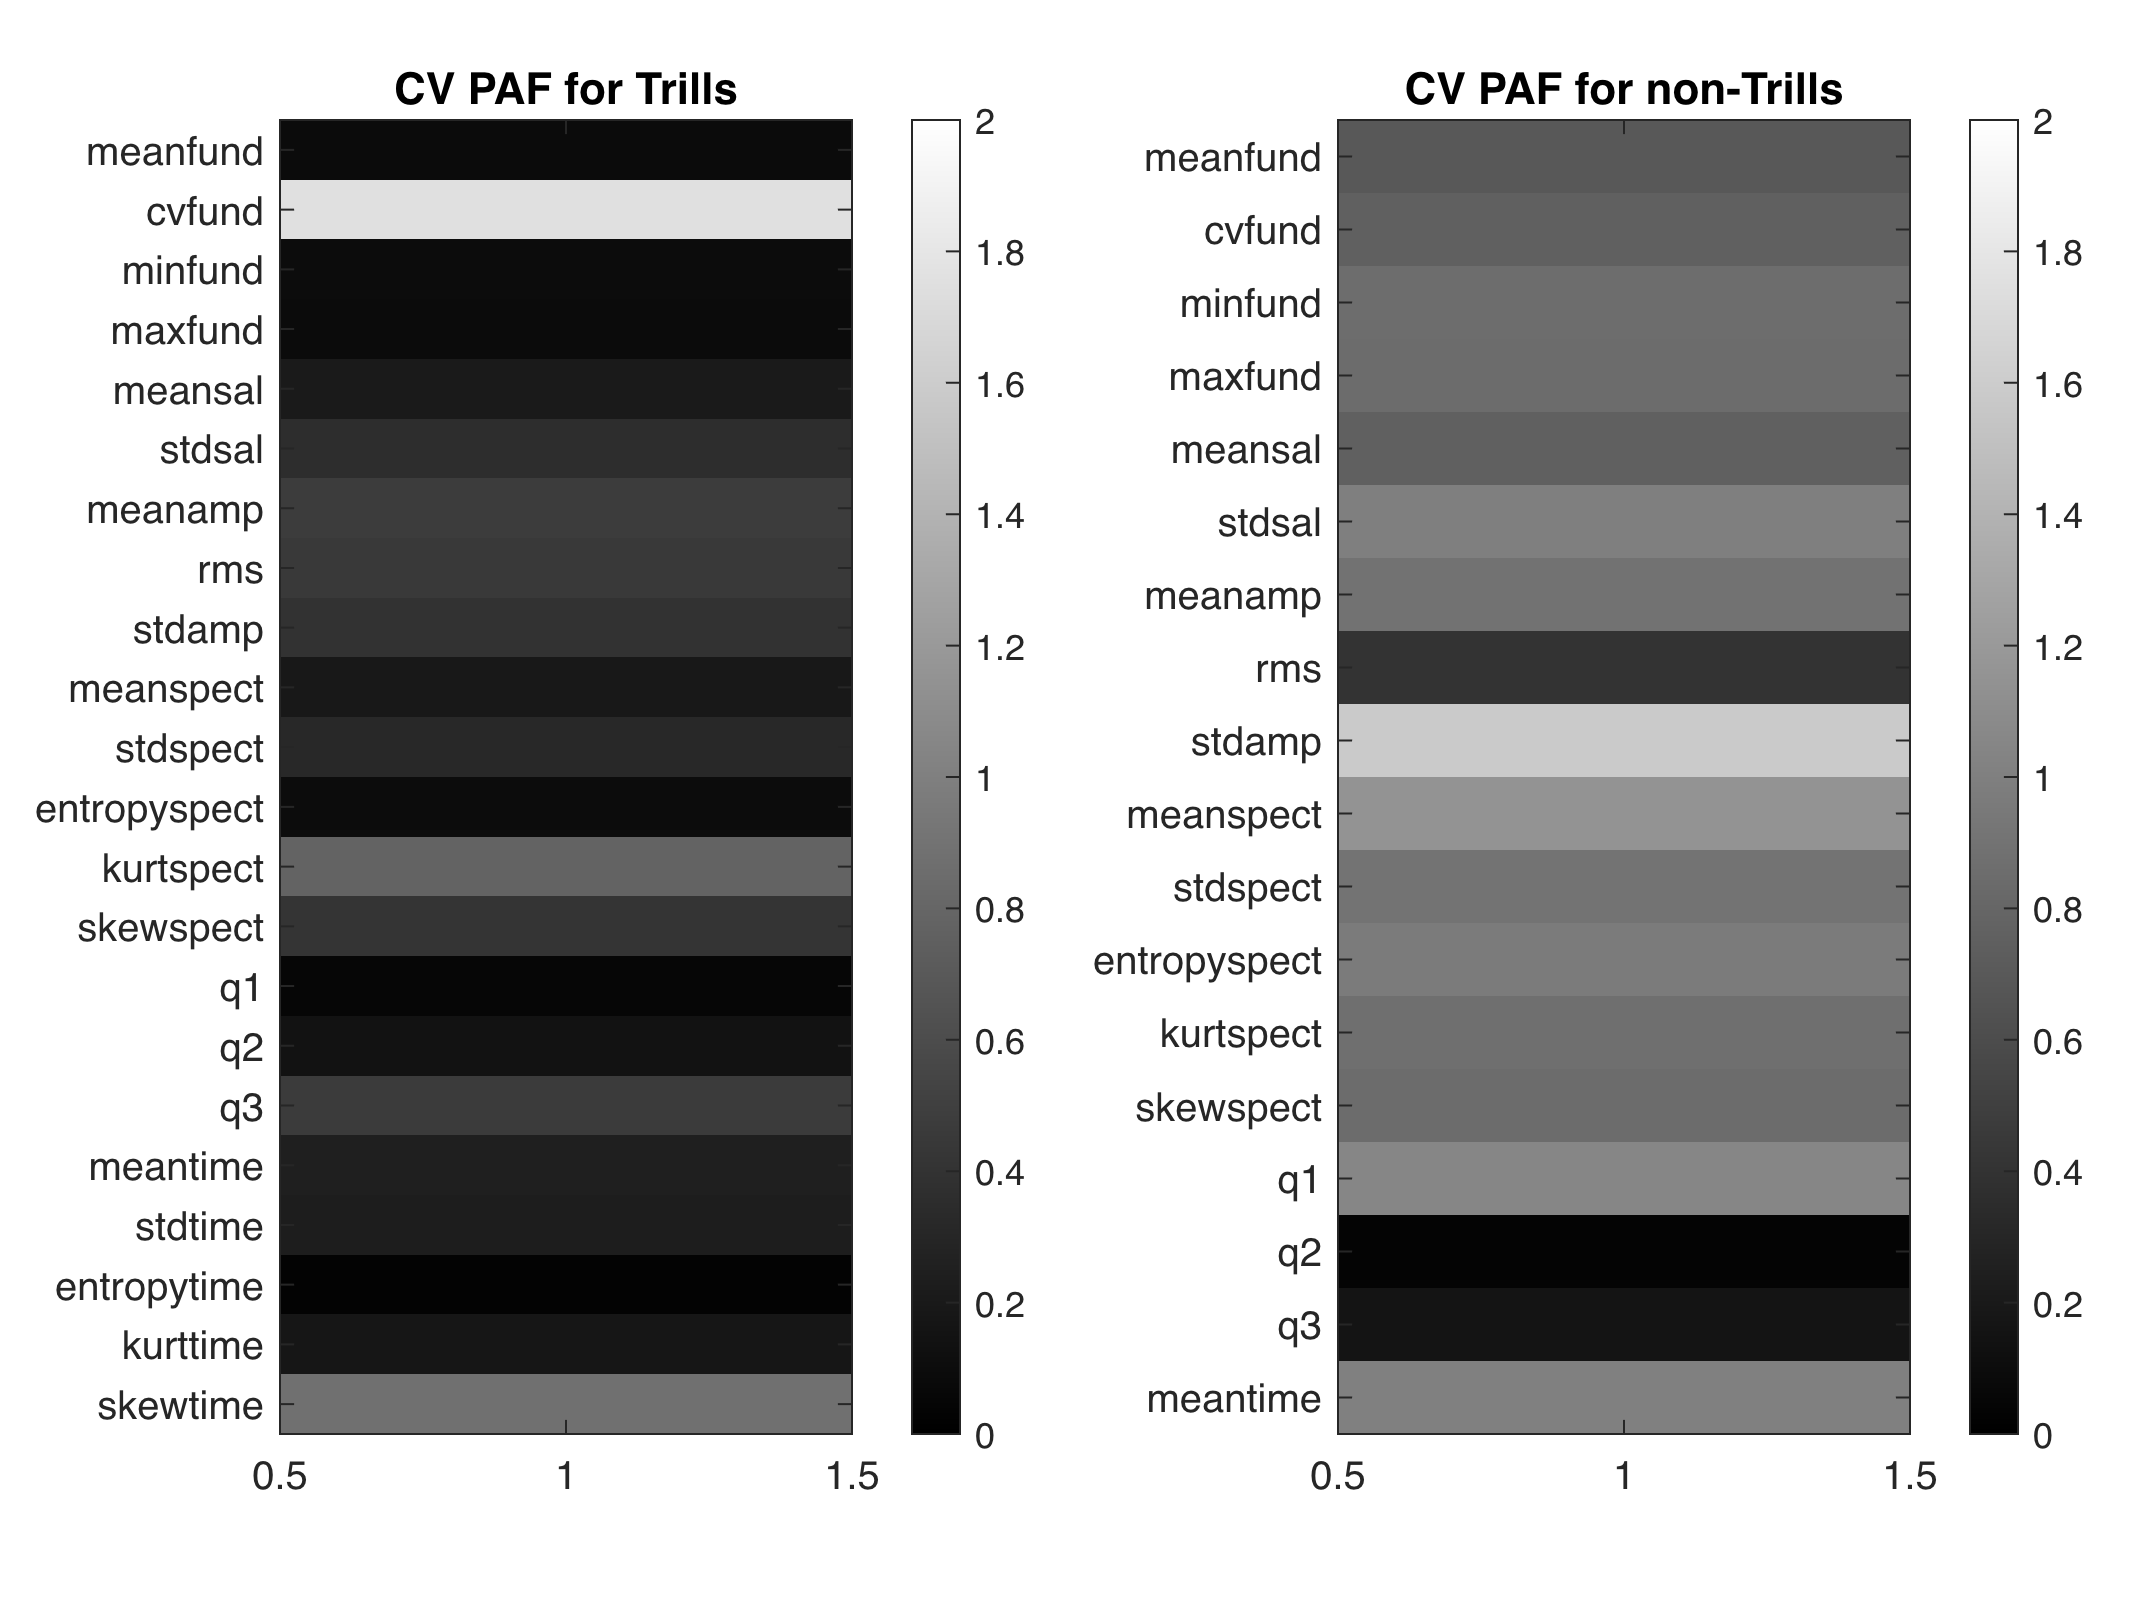

figure
tiledlayout(1,2)
nexttile
imagesc(CVPAF_T)
colorbar()
title('CV PAF for Trills')
set(gca, 'YTick', 1:length(CVPAF_T), 'YTickLabel', CVPAFnames)
caxis('manual');
caxis([0 2]); 
colormap('gray')
nexttile
imagesc(CVPAF_NT)
colorbar()
title('CV PAF for non-Trills')
set(gca, 'YTick', 1:length(CVPAF_NT), 'YTickLabel', CVPAFnames)
caxis('manual');
caxis([0 2]);
colormap('gray')

save(fullfile(Path2AllData,sprintf('%s_PAF_Trills_%s.mat', BatID, RecDevice)), 'BatAllTrillsMPS','Voc_wf','Voc_wt','ROI','Wf_ROI','Wt_ROI','SeparateContour','CVMPS4Contour','Level')

function outyy = mysmooth(yy,Span)
        if nargin<2
            Span = 5;
        end
        outyy=nan(size(yy));
        for ii=1:length(yy)
            if ii==1 || ii==length(yy)
                outyy(ii) = yy(ii);
            elseif ii<=((Span-1)/2)
                HalfSpan = ii-1;
                outyy(ii) = nanmean(yy(1:(ii+HalfSpan)));
            elseif (length(yy)-ii) <= ((Span-1)/2)
                HalfSpan = length(yy)-ii;
                outyy(ii) = nanmean(yy((ii-HalfSpan):end));
            else
                HalfSpan = (Span-1)/2;
                outyy(ii) = nanmean(yy((ii-HalfSpan):(ii+HalfSpan)));
            end
        end
end

function [MPS, Wf, Wt] = mps_calc(Y, FS, Max_freq)
        % spectrogram parameters
        Spec_sample_rate = 1000; % sampling rate Hz
        Freq_spacing = 100; % width of the frequency window for the FFT Hz
        Min_freq = 100; % highpass filter before FFT Hz
        if nargin<3
            Max_freq = 50000; % low pass filter before FFT
        end
        % MPS parameters
        Window = 0.1;% duration of the window in sec when binning the spectrogram
        Norm = 1; % boolean to indicate if you want to normalize or not the MPS (zscore of the spectrogram before 2Dfft
        BiosoundObj = py.soundsig.sound.BioSound(py.numpy.array(Y), pyargs('fs', FS));
        spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing, Min_freq, Max_freq)
        mpsCalc(BiosoundObj, Window, Norm)
        MPS = double(BiosoundObj.mps);
        Wf = double(BiosoundObj.wf);
        Wt = double(BiosoundObj.wt);
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,Log, YLim, XLim,CLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<5
        Log=1;
    end

    if nargin<6
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<7
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<8
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end

function plot_spectro(logB,DBNOISE, to, fo, f_low, f_high,t_max)
%     logB = 20*log10(abs(s));
    maxB = max(max(logB));
    minB = maxB-DBNOISE;            

    Im = imagesc(to*1000,fo,logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]); 
    cmap = spec_cmap();
    colormap(Im.Parent,cmap);

    v_axis = axis; 
    v_axis(3)=f_low; 
    v_axis(4)=f_high;
    v_axis(2) = t_max;
    axis(v_axis);
    xlabel('time (ms)'), ylabel('Frequency (Hz)');
end